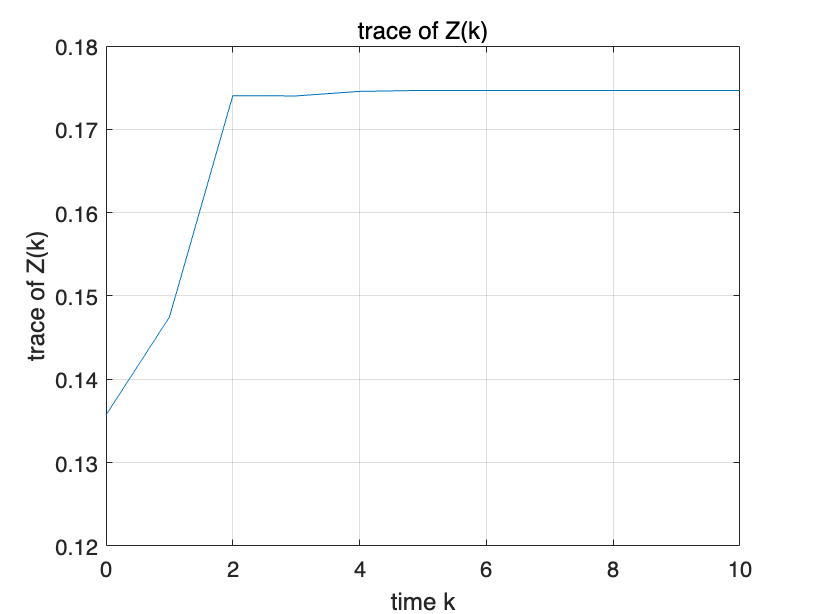

X0 = [0.1,0;0,0.1];
w=1;
v=0.5;
N=11;
N2=11;
A = [-0.08, -1; 0.7, 0.1];
B = [0.34; 0.3];
C = [0, 3];

Bw =[0.34; 0.3];

covww=w*eye(N2);
coxvv=v*eye(N2);

M = cell(N2);

Z = cell(N2);

M{1} = [0.1,0;0,0.1];
tr_z = zeros(N2);
covyyk0 = zeros(N2);

for k = 1:N2
    temp1 = C * M{k} * (C.') + v ;
    temp2 = inv(temp1);
    Z{k} = M{k} - M{k} * (C.')* temp2 * C * M{k};
    tr_z(k) = trace(Z{k});
    M{k+1} = A * Z{k} * (A.') + Bw * w * (Bw.');
    covyyk0(k) = temp1;
   % M{k+1} = A * M{k} * (A.') + B * w * (B.') - A * M{k} * (C.')* temp2 * C * M{k} * (A.');

end

figure();
plot(0:1:N2-1,tr_z)
title('trace of Z(k)');
xlabel('time k');
ylabel('trace of Z(k)');
xlim([0 N2-1]);

ylim([0.12,0.18])
grid on;

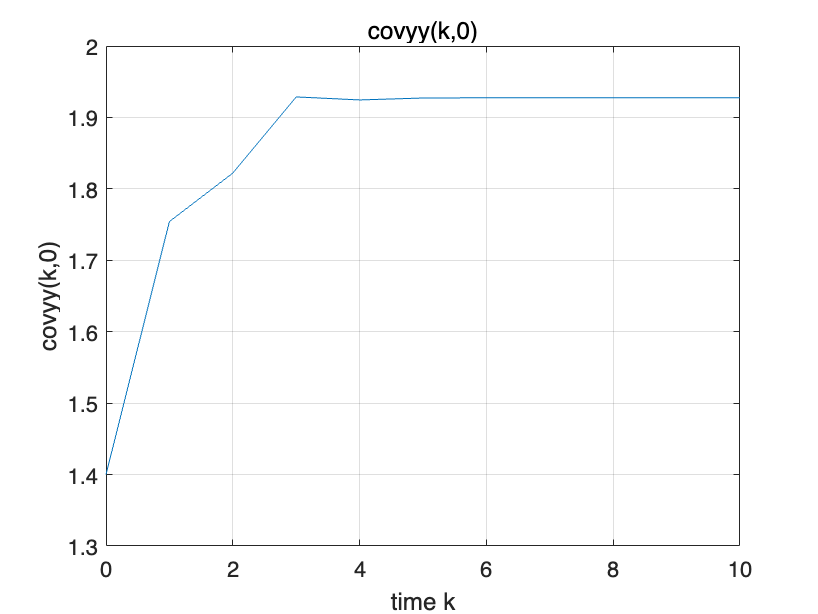


figure();
plot(0:1:N2-1,covyyk0)
title('covyy(k,0)');
xlabel('time k');
ylabel('covyy(k,0)');
xlim([0 N2-1]);
ylim([1.3 2])
grid on;